# Visual degrees and retinal mm

It is sometimes necessary to convert measurements made along the retina from one set of units (degrees of visual angle) to another (millimeters). While there are rules-of-thumb for this conversion (e.g., 0.3 mm / degree), the precise value is complicated to obtain. This is because of individual varation in the ellipsoidal dimensions of the retina, as well as in the optics and accommodative state of the eye.

This demo explores the concepts and details related to this conversion.

UNDER DEVELOPMENT

## Visual field position

Given an eye in a particular accommodative state, and given a point in object space, there is a unique location on the retina where that point is imaged (even if that point is the central tendency of a blurred area). What becomes complicated, however, is when we wish to describe the location in object space in terms of *angular visual field* position. With some consideration we come to realize that the assignment of an angular position to a point in object space depends upon specification of points of reference, and that these points of reference can change.

It is often useful to identify points in object space by their visual field position. This is expressed as the horizontal and vertical angles (in, e.g., degrees) of a point in object space with respect to an eye-based coordinate frame. In casual usage, the eye-based coordinate frame may have its origin at the front of the eye, with the horizontal and vertical planes defined with respect to gravity. One advantage of describing locations in terms of visual field position, and size in terms of visual degrees, is that the absolute distance of the object need not be specified.

This simple definition of visual angle is good enough in most circumstances. If, however, greater precision is waranted, then the next stage of complexity is to define visual field position with respect to the* nodal points *of the eye. In a simple, paraxial optical system, a ray directed towards the *incident* node will appear to leave from the optical system at the *emergent* node unchanged in direction of travel (i.e., the incident and emergent rays are parallel). A ray that has the property of entering and exiting an optical system traveling in the same direction is termed a *nodal ray*.

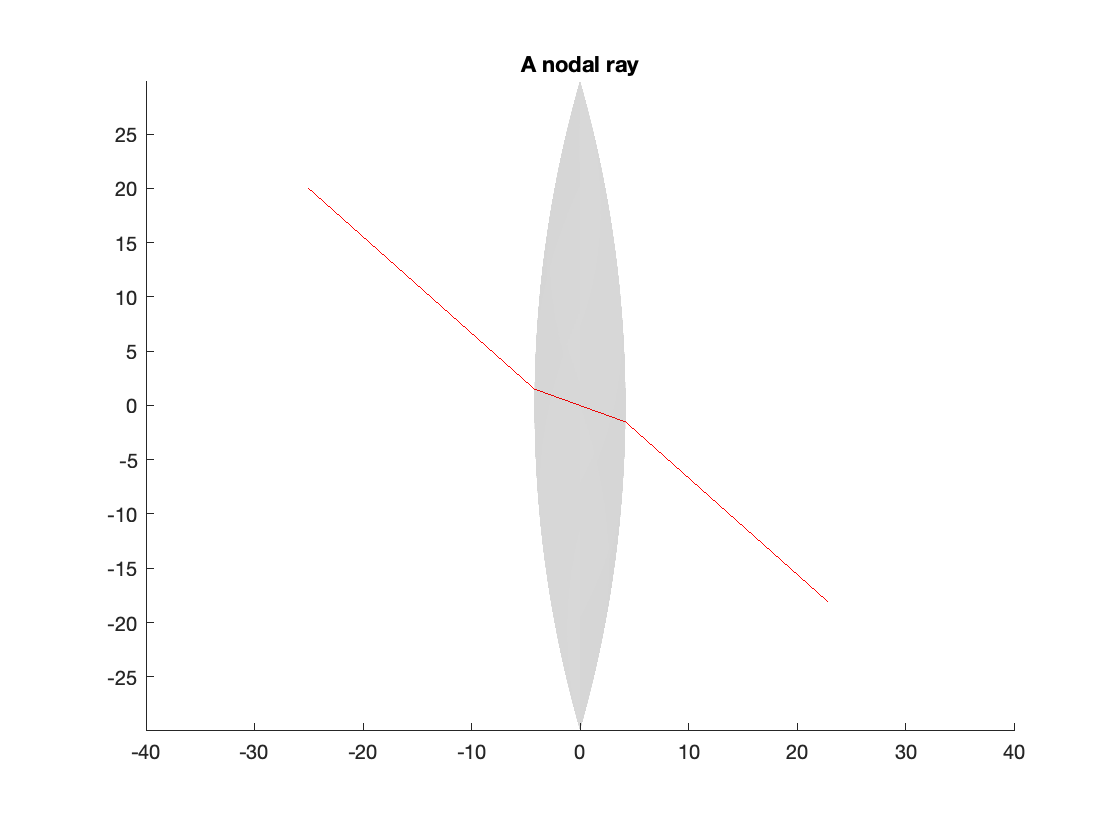

opticalSystem = addBiconvexLens( initializeOpticalSystem, 0, 20, 30, 2);
[rayPath,outputRay] = findNodalRay([-25,0,20],opticalSystem);
plotOpticalSystem(opticalSystem,'newFigure',false,'rayPath',rayPath,'outputRay',outputRay,'outputRayScale',25);
view(0,0);
xlim([-40 40])
title('A nodal ray');

Given the incident and emergent nodes of an eye, one may assert that nodal rays arising from a particular visual field position will enter the optics of the eye and exit towards the retina at the same angles, creating a nice correspondence between points in object space and points on the retina.

However, this characterization of visual angle masks further complexity. The eye (and the model eye) optical system does not have unique nodal points. While one may estimate an approximation to the incident and emergent nodal points, this estimated location itself will change depending upon (e.g.) the accommodative state of the eye. Moreover, there is no guarantee that a nodal ray that arises from a particular visual field location will pass through the approximate incident nodal point.

Drasdo & Fowler calculated this conversion as a function of position on the retina for an emmetropic eye:

- Drasdo N, Fowler CW. Non-linear projection of the retinal image in a wide-angle schematic eye. Br J Ophthalmol. 1974;58(8):709

Here I demonstrate how to calculate this value for different positions on the retina, and for eyes of different sizes and optics. We then examine the source of diffrences in the current model from the values reported by Drasdo & Fowler

## Basic calculation

The unit conversion is calculated for a particular eye under study. We first define a model eye structure, accommodated at infinity:

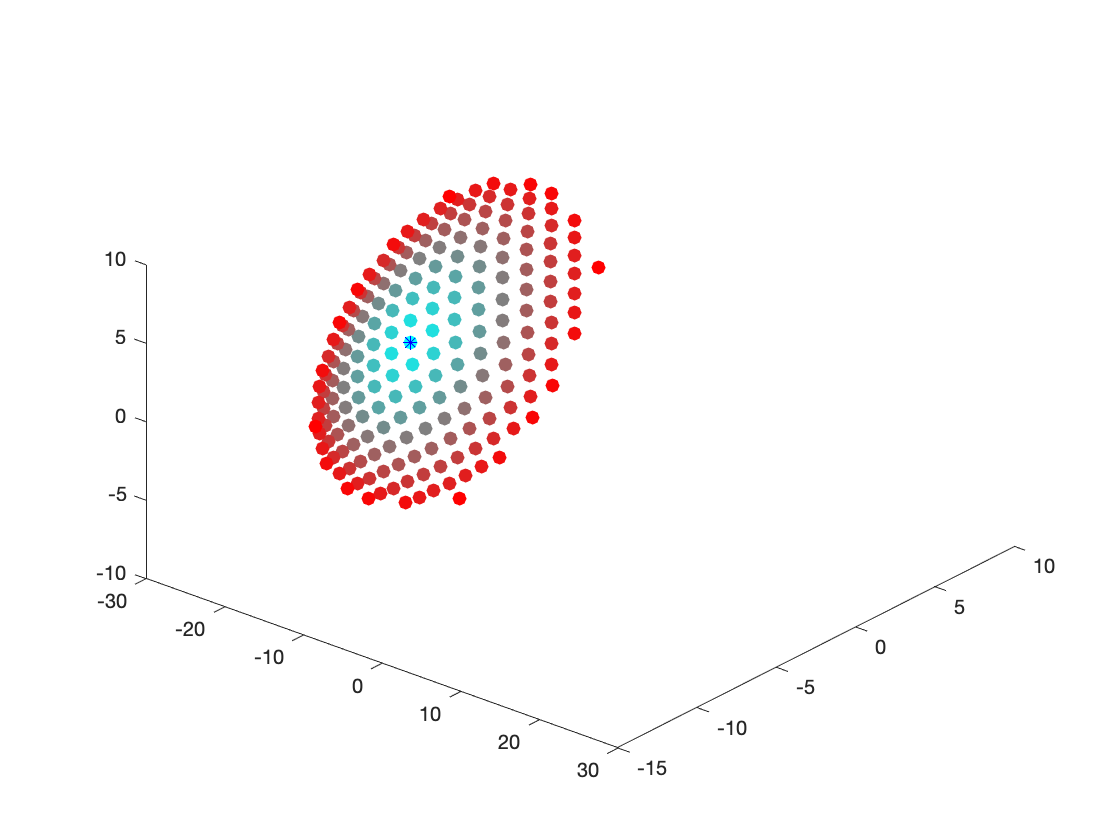

eye = modelEyeParameters('accommodation',1.5);
foveaDegField = eye.landmarks.fovea.degField;
rayOriginDistance = 1000/10;
angleReferenceCoord = eye.landmarks.incidentNode.coords;
distanceReferenceCoord = calcPrincipalPoint(eye);
figure
plotOpticalSystem(opticalSystem,'newFigure',false);
hold on
for hh = -40:5:40
    for vv = -40:5:40
        if norm([hh vv])>40
            continue
        end
        fieldPoint = [hh vv]+foveaDegField;
        rayPath = calcNodalRayFromField(eye,fieldPoint,rayOriginDistance,angleReferenceCoord,distanceReferenceCoord);
        color = [norm([hh vv])/40 1-norm([hh vv])/40 1-norm([hh vv])/40];
        scatter3(rayPath(1,end),rayPath(2,end),rayPath(3,end),50,color,'filled','o');
    end
end
plot3(eye.landmarks.fovea.coords(1),eye.landmarks.fovea.coords(2),eye.landmarks.fovea.coords(3),'*b');
xlim([-30 30]);

We can obtain the mm/deg of field angle for a point on the longitudinal axis with this function:

mmPerDeg = calcMmRetinaPerDeg(eye)

mmPerDeg = 0.2796

This value is reasonably close to the 0.3 mm / degree rule-of-thumb.

## Visual degrees at the fovea

To be a bit more precise, we can define angle with respect to the approximate incident nodal point of the eye, and the field location as corresponding to the fovea:

fieldAngularPosition = eye.landmarks.fovea.degField;
rayOriginDistance = 1500;
angleReferenceCoord = eye.landmarks.incidentNode.coords;

We now call the function with these optional inputs:

mmPerDeg = calcMmRetinaPerDeg(eye,fieldAngularPosition,rayOriginDistance,angleReferenceCoord)

mmPerDeg = 0.2791

As can be seen, there is a small difference in the unit relationship depending upon the position in the visual field that we choose to interogate.

## Unit conversion as a function of field position

We can repeat the calculation, now for positions along the horizontal meridian, relative to the fovea, and plot the resulting function:

horizontalOffset = -40:5:40;
for ii = 1:length(horizontalOffset)
    thisLocation = [horizontalOffset(ii)+fieldAngularPosition(1), fieldAngularPosition(2)];
    mmPerDeg(ii) = calcMmRetinaPerDeg(eye,thisLocation,rayOriginDistance,angleReferenceCoord);
end
figure
plot(horizontalOffset,mmPerDeg,'-k')
ylabel('mm/deg');
xlabel('horizontal field location relative to fovea [deg]');
xlim([-40 40])

## Comparison to Drasdo & Fowler

One of the "species" of model eye available in the software is Drasdo & Fowler 1974. We can examine the behavior of this model eye.

eye = modelEyeParameters('species','Drasdo');
fieldAngularPosition = eye.landmarks.fovea.degField;
rayOriginDistance = 1500;
angleReferenceCoord = eye.landmarks.incidentNode.coords;

for ii = 1:length(horizontalOffset)
    thisLocation = [horizontalOffset(ii)+fieldAngularPosition(1), fieldAngularPosition(2)];
    mmPerDeg(ii) = calcMmRetinaPerDeg(eye,thisLocation,rayOriginDistance,angleReferenceCoord);
end
hold on
plot(horizontalOffset,mmPerDeg,'-r')

The result is similar to that provided by the current model eye, although with lower values overall. This may be attributed to small differences in the axial length of the modeled eyes, and the location of the approximate nodal points.

Interestingly, Figure 4 of Drasdo & Fowler (1974) provides the outcome of their modeling, with a fairly different looking result. Using [https://automeris.io/WebPlotDigitizer/,](https://automeris.io/WebPlotDigitizer/,) I extracted the values for the  mm/deg relationship in the horizontal ("radial") direction from Figure 4, and add this to the plot in blue

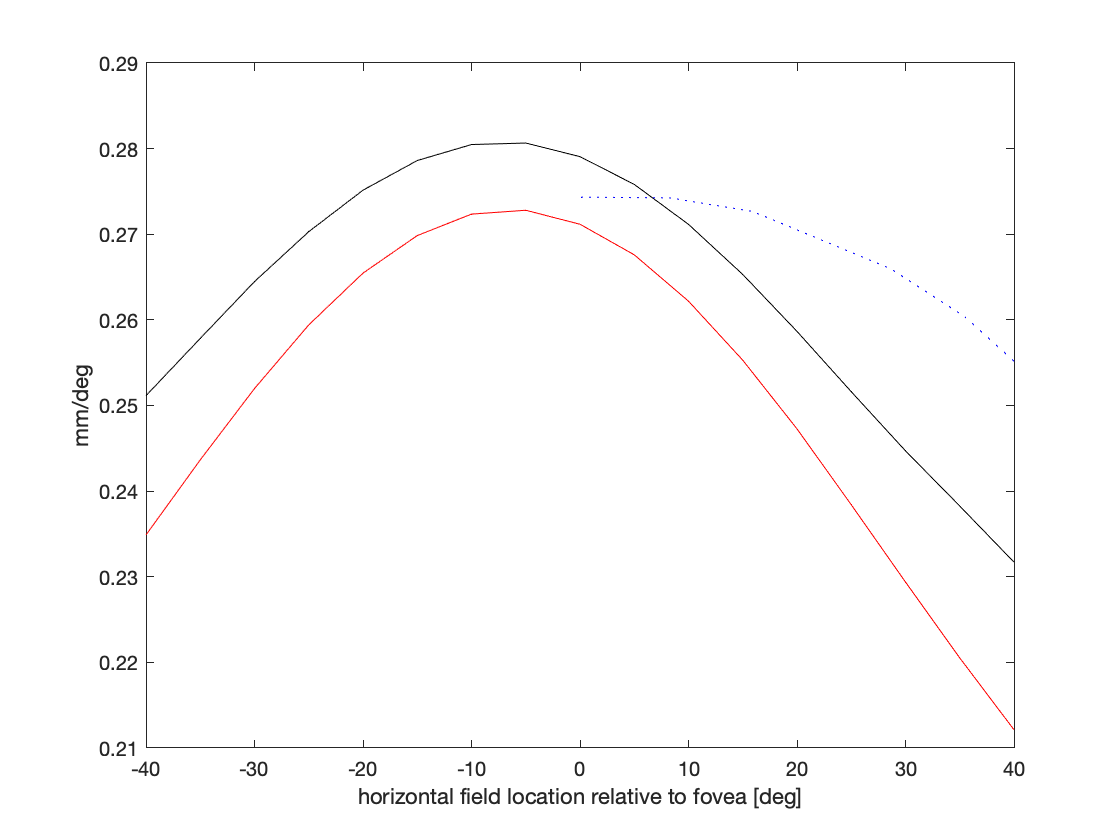

dfData = [0.14344384771044716, 0.27432995500303115
8.285589870132085, 0.27424798709005377
15.912448022951018, 0.2726611395247569
28.606801629112276, 0.2659897198575808
35.45325694379222, 0.26038388305911087
42.54348141633724, 0.2522588136852262
47.85261144647752, 0.24415167479230532
53.65995269768356, 0.23352274182668914
61.48148464382381, 0.2178399747265602
69.7990932299627, 0.1991320793381091
77.34697188329818, 0.1789218657946192
83.8664093784954, 0.1562052271621172
88.11934869662483, 0.13904831837703538
93.88826748862272, 0.11935936953013604
99.93297415449246, 0.1047012013422246
];
plot(dfData(:,1),dfData(:,2),':b')